# Function 1:


$$f\left(z\right)=z^3 -1$$


The complex roots of this function are:

-0.500 + 0.8660i

-0.500 - 0.8600i

1.000 + 0.0000i

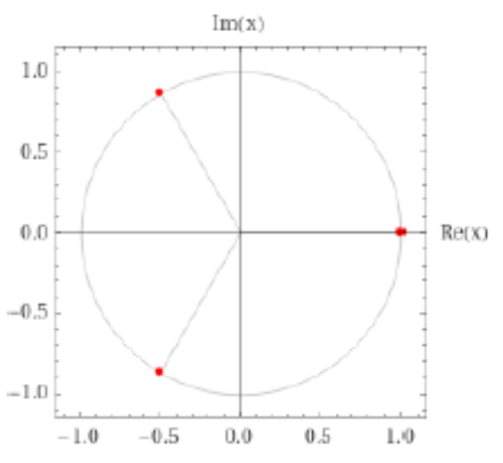

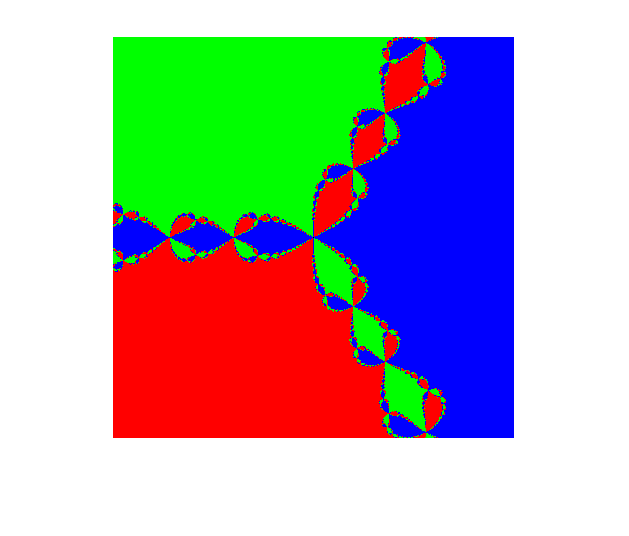

clc;
x=-2:.01:2;
x=x+eps;
y=x;
i=complex(0,1);
[X Y]=meshgrid(x,y);
Z=X+i*Y;
for j=1:64
    Z=Z-(Z.^3-1)./(3*Z.^2);
end
%coefficients of x^3-1 in order are 1 0 0 -1
r=roots([1 0 0 -1]);
Z1=abs(Z-r(1))<=0.1;
Z2=abs(Z-r(2))<=0.1;
Z3=abs(Z-r(3))<=0.1;
a(:,:,1)=Z1*1;
a(:,:,2)=Z2*1;
a(:,:,3)=Z3*1;
figure
imshow(a)